# Use Least Median of Squares Method to Find Inliers

Load the putatively matched points into the workspace.

load stereoPointPairs
[fLMedS,inliers] = estimateFundamentalMatrix(matchedPoints1,matchedPoints2,NumTrials=2000)

fLMedS =     0.0000   -0.0000   -0.0042
    0.0000    0.0000   -0.0444
    0.0030    0.0421    0.9981


inliers = 18×1 logical array
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1


Load the stereo images.

I1 = imread("viprectification_deskLeft.png");
I2 = imread("viprectification_deskRight.png");

Show the putatively matched points.

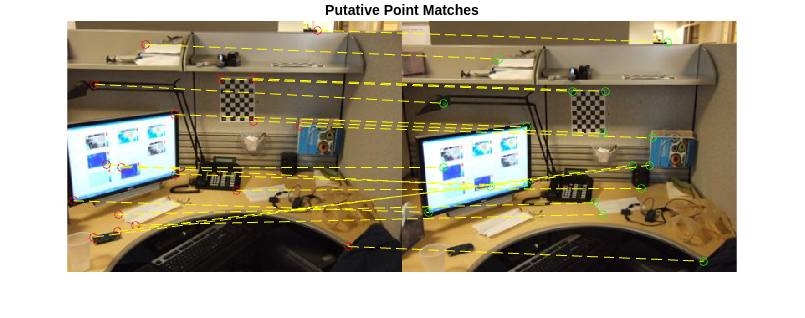

figure;
showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,"montage",PlotOptions=["ro","go","y--"]);
title("Putative Point Matches");

Show the inlier points.

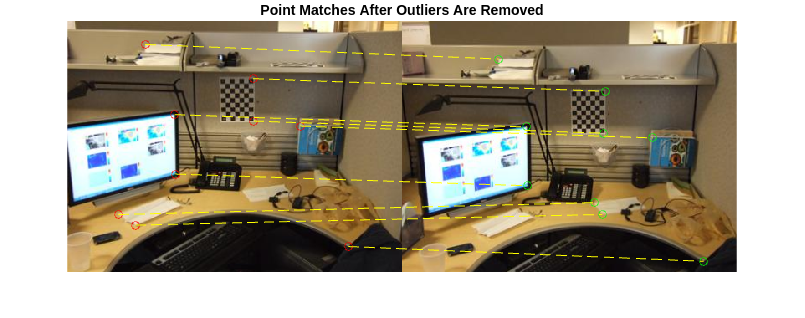

figure;
showMatchedFeatures(I1,I2,matchedPoints1(inliers,:),matchedPoints2(inliers,:),"montage",PlotOptions=["ro","go","y--"]);
title("Point Matches After Outliers Are Removed");

*Copyright 2012 The MathWorks, Inc.*